data = X_total_noout;
[PC_score, PC_coeff, rates, cum_rates] = feature_pca(data, 20);

format short
rates

rates =     0.6040
    0.1254
    0.1006
    0.0457
    0.0341
    0.0232
    0.0201
    0.0072
    0.0063
    0.0053


cum_rates

cum_rates =     0.6040
    0.7294
    0.8300
    0.8757
    0.9097
    0.9329
    0.9530
    0.9602
    0.9665
    0.9718


% X_pca = PC_score(:,1:20);

group = string(y_total_noout);
group(group == "1") = "zd958";
group(group == "2") = "jd20";
group(group == "3") = "nh816";
group(group == "4") = 'jh5';

% figure;
% scatter3(PC1(1:150), PC2(1:150), PC3(1:150), 20, "red", "filled")
% hold on
% scatter3(PC1(151:300), PC2(151:300), PC3(151:300), 20, "green", "filled")
% hold on
% scatter3(PC1(301:450), PC2(301:450), PC3(301:450), 20, "blue", "filled")
% hold on
% scatter3(PC1(451:600), PC2(451:600), PC3(451:600), 20, "magenta", "filled")
% xlabel('PC1')
% ylabel('PC2')
% zlabel('PC3')
% legend([{"zd958"},{"jd20"},{"nh816"}, {"jh5"}])

PC1 = PC_score(:, 1);
PC2 = PC_score(:, 2);
PC3 = PC_score(:, 3);
PC4 = PC_score(:, 4);

% figure;
% gscatter(PC1, PC3, group)
% xlabel("PC1(61.28%)")
% ylabel("PC3(10.24%)")
% legend("Location","southeast")
% set(gca,'fontsize',30, 'FontWeight','bold');

% figure;
% plot(effshift, PC_coeff(:, 3));
% xlim([400, 1800])
% xlabel('Raman Shift(cm^{-1})')
% ylabel('Loadings on PC3')

% figure;
% 
% subplot(2,1,1)
% plot(effshift, PC_coeff(:, 1));
% xlim([400, 1800])
% xlabel('Raman Shift(cm^{-1})')
% ylabel('Loadings on PC1')
% title('a')
% 
% x = ginput;
% k = size(x,1);
% hold on
% for i = 1:k
%     plot(x(i,1),x(i,2),'r+')    
%     text(x(i,1), x(i,2), sprintf('%d',round(x(i,1))))
% end 
% 
% subplot(2,1,2)
% plot(effshift, PC_coeff(:, 3));
% xlim([400, 1800])
% xlabel('Raman Shift(cm^{-1})')
% ylabel('Loadings on PC3')
% title('b')
% 
% x = ginput;
% k = size(x,1);
% hold on
% for i = 1:k
%     plot(x(i,1),x(i,2),'r+')    
%     text(x(i,1), x(i,2), sprintf('%d',round(x(i,1))))
% end  

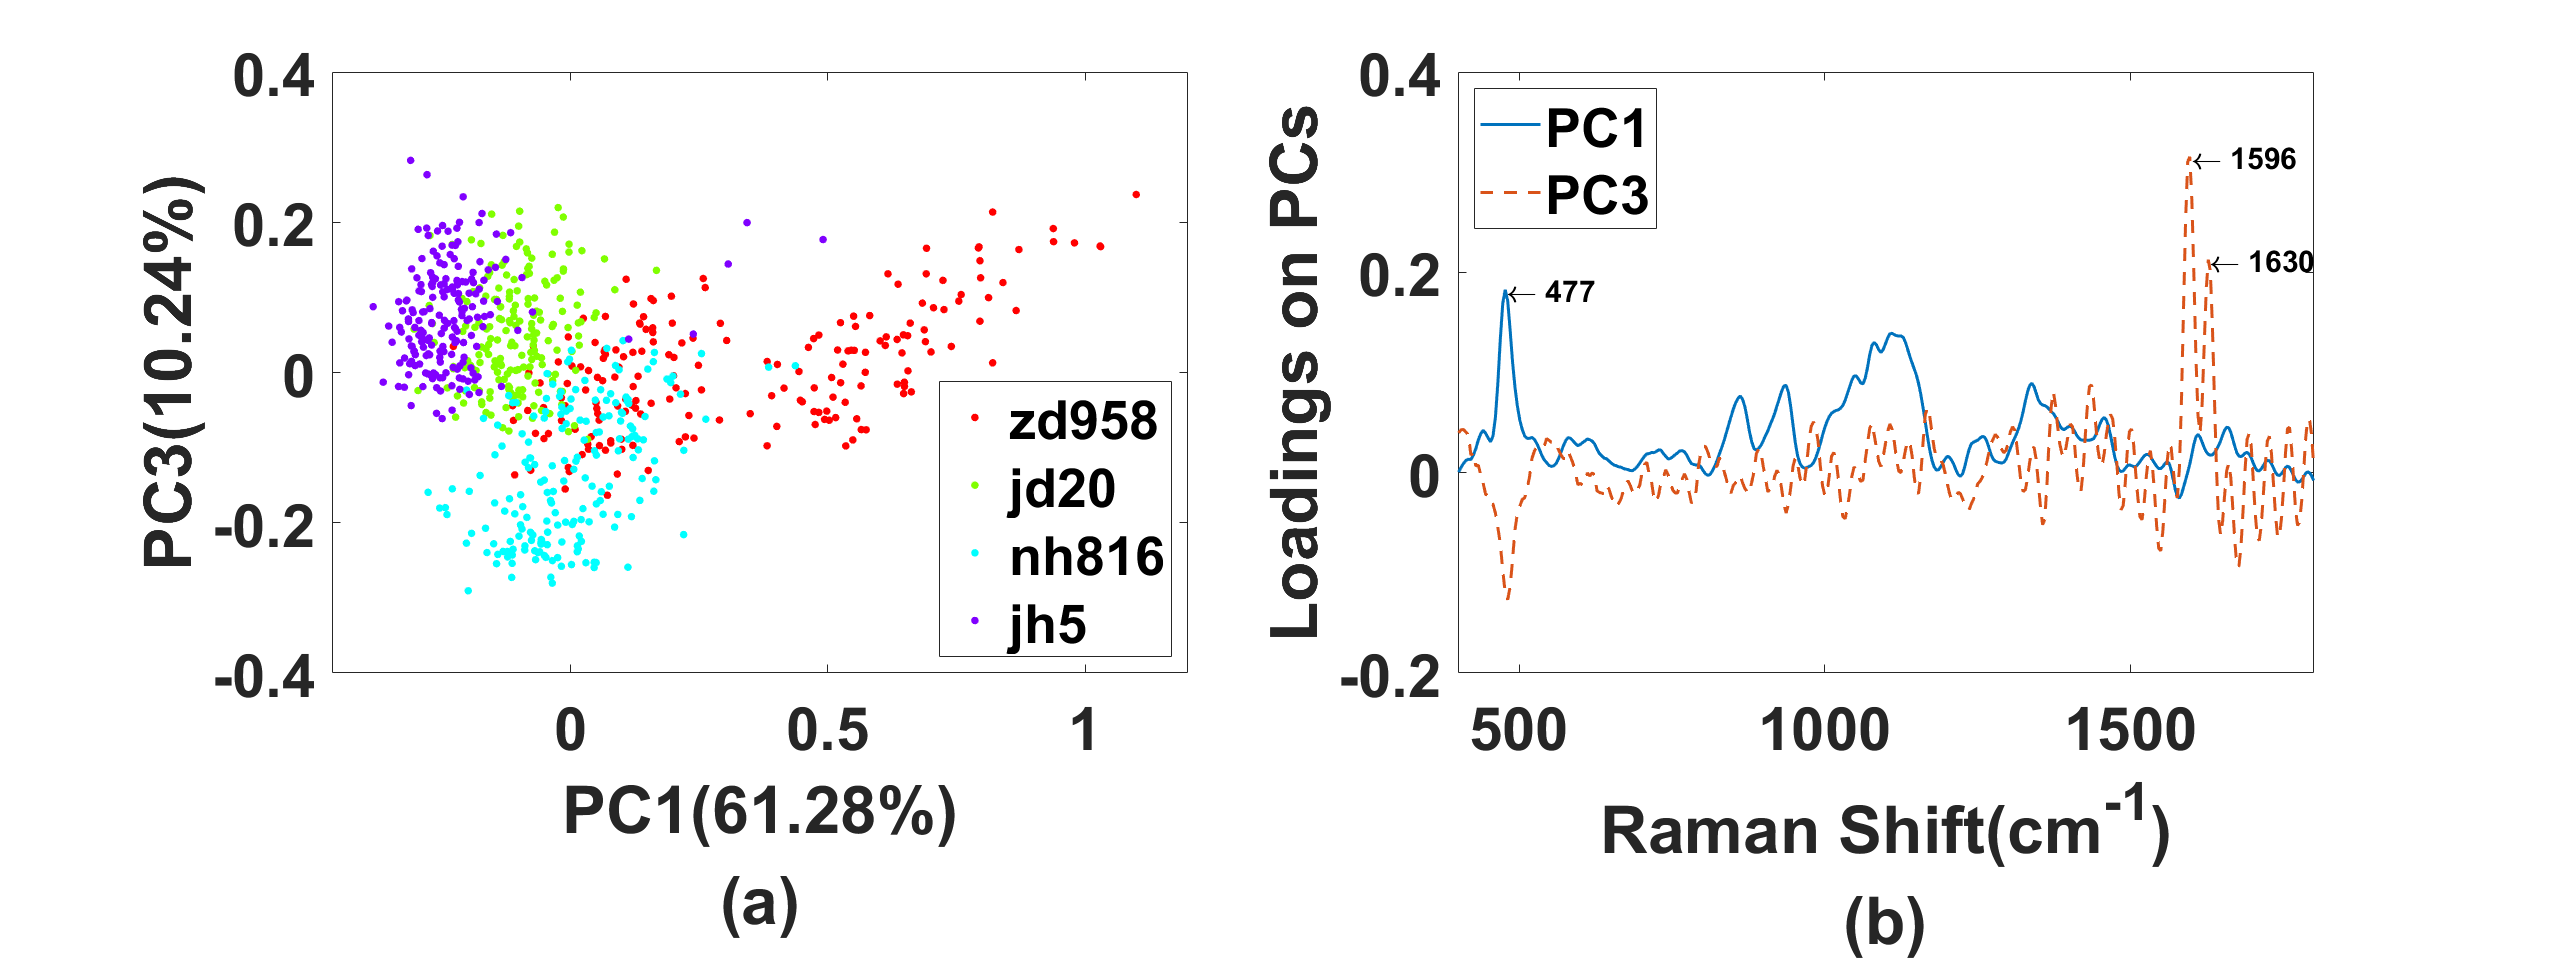

figure('Units','normalized', 'Position', [0, 0, 1, 0.6]);

subplot(1,2,1)
gscatter(PC1, PC3, group)
xlabel({'PC1(61.28%)', '(a)'})
ylabel("PC3(10.24%)")
legend("Location","southeast")
set(gca,'fontsize',30, 'FontWeight','bold');

subplot(1,2,2)
PCloading1 = PC_coeff(:, 1);
PCloading3 = PC_coeff(:, 3);
plot(effshift, PCloading1, "LineWidth", 1.5);
hold on;
plot(effshift, PCloading3, "LineStyle","--", "LineWidth", 1.5);
xlim([400, 1800])
xlabel({'Raman Shift(cm^{-1})', '(b)'})
ylabel('Loadings on PCs')
legend([{"PC1"},{"PC3"}], "Location", "northwest")
set(gca,'fontsize',30, 'FontWeight','bold');

[~, mark1] = min(abs(effshift - 477));
[~, mark2] = min(abs(effshift - 1596));
[~, mark3] = min(abs(effshift - 1627));

text(effshift(mark1),PCloading1(mark1), '\leftarrow 477', 'FontSize',15, 'FontWeight','bold')
text(effshift(mark2),PCloading3(mark2), '\leftarrow 1596', 'FontSize',15, 'FontWeight','bold')
text(effshift(mark3),PCloading3(mark3), '\leftarrow 1630', 'FontSize',15, 'FontWeight','bold')

% subplot(3,3,9)
% plot(effshift, PC_coeff(:, 9));
% xlim([400, 1800])
% xlabel('Raman Shift(cm^{-1})')
% ylabel('Loadings on PC9')

% data1 = X1;
% [PC_score1, PC_coeff1, rates1, cum_rates1] = feature_pca(data1, 10);
% group1 = string(y1);
% group1(group1 == "1") = "zd958";
% group1(group1 == "2") = "zd958nc";
% axis1 = PC_score1(:, 1);
% axis2 = PC_score1(:, 2);
% gscatter(axis1, axis2, group1)

data = X;
label = y;
vsel_pca = [mark1, mark2, mark3];
train_data  = data(training(cvp), vsel_pca);
train_label = label(training(cvp));
test_data   = data(test(cvp), vsel_pca);
test_label  = label(test(cvp));

rng(1); % For reproducibility
randIndex1 = randperm(size(train_data,1));
rng(1); % For reproducibility
randIndex2 = randperm(size(test_data,1));

train_data  = train_data(randIndex1, :);
train_label = train_label(randIndex1);
test_data   = test_data(randIndex2, :);
test_label  = test_label(randIndex2);

.*
optimization finished, #iter = 234
nu = 0.542304
obj = -467.172476, rho = 1.426107
nSV = 97, nBSV = 86
*
optimization finished, #iter = 45
nu = 0.195350
obj = -151.787426, rho = -0.049711
nSV = 35, nBSV = 31
*
optimization finished, #iter = 25
nu = 0.036737
obj = -20.342401, rho = -0.092127
nSV = 9, nBSV = 5
*
optimization finished, #iter = 128
nu = 0.123125
obj = -92.390261, rho = -0.496880
nSV = 26, nBSV = 18
*
optimization finished, #iter = 33
nu = 0.026923
obj = -17.681352, rho = -0.435813
nSV = 9, nBSV = 3
*
optimization finished, #iter = 40
nu = 0.267928
obj = -211.553411, rho = -0.221054
nSV = 46, nBSV = 43
Total nSV = 171
*.*
optimization finished, #iter = 203
nu = 0.609830
obj = -531.090497, rho = 1.639686
nSV = 108, nBSV = 98
*
optimization finished, #iter = 94
nu = 0.204626
obj = -166.707479, rho = 0.049481
nSV = 39, nBSV = 32
*
optimization finished, #iter = 42
nu = 0.072676
obj = -47.722050, rho = 0.070148
nSV = 16, nBSV = 11
*
optimization finished, #iter = 36
nu = 0.1

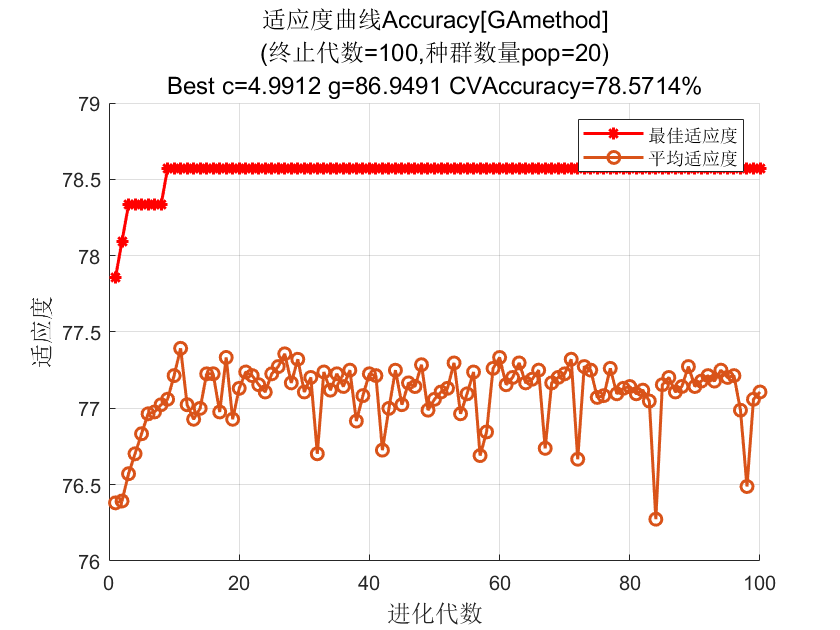

tic
[bestacc, bestc, bestg] = gaSVMcgForClass(train_label, train_data);

toc

历时 40.657982 秒。


s = 0;
t = 2;
c = bestc;
g = bestg;
options = [' -s ',num2str(s),' -t ',num2str(t),' -c ',num2str(c),' -g ',num2str(g)]; 
model = libsvmtrain(train_label, train_data, options); 

*.*
optimization finished, #iter = 397
nu = 0.551719
obj = -548.216414, rho = 0.958447
nSV = 121, nBSV = 110
*
optimization finished, #iter = 75
nu = 0.200123
obj = -189.423244, rho = -0.124898
nSV = 45, nBSV = 40
*
optimization finished, #iter = 100
nu = 0.053191
obj = -39.392891, rho = -0.086201
nSV = 14, nBSV = 8
*
optimization finished, #iter = 69
nu = 0.104086
obj = -88.796269, rho = -0.456206
nSV = 25, nBSV = 18
*
optimization finished, #iter = 57
nu = 0.035562
obj = -23.435757, rho = -0.282299
nSV = 12, nBSV = 4
*
optimization finished, #iter = 121
nu = 0.324292
obj = -316.573902, rho = 0.473153
nSV = 71, nBSV = 66
Total nSV = 225



[train_pred_label, train_acc, ~]...
           = libsvmpredict(train_label, train_data, model);

Accuracy = 80% (336/420) (classification)


[test_pred_label, test_acc, ~]...
           = libsvmpredict(test_label, test_data, model);

Accuracy = 79.4444% (143/180) (classification)
